## Eercise 1: Correspondence with the Reference Triangle

Usually the **reference** triangular element, $$T^R$, is the triangle defined by the vertices


$$$\hat{v}_1=(0,0), \hat{v}_2=(1,0), \hat{v}_3=(0,1)$$


We can use barycentric coordinates to make a **correspondence** between the reference triangle and every other triangle. Let's consider the preivous exemple triangle 

$v_1=(1,1), v_2=(3,2), v_3=(2,4)$.

Assuming that each vertex has its correspondence $\hat{v}_i\mapsto v_i$, using the barycentric coordinates we obtain the point correspondence:

$$ \hat{p}\mapsto p\in T^R = \alpha_1 v_1+\alpha_2 v_2+\alpha_3 v_3\in T^K$,

compute the image of the point $\hat{p} =(0.4, 0.2)\in T^R$ on the triangle $T^{K}$.

**Remark. **Files required: `baryCoordQuad.m. `Be sure it is placed in the current folder!

clearvars
close all

vertexsR = [0,0;
    1,0;
    0,1]; %vertexs of the reference triangle, R

vertexsK=[1,1; 
    3,2;
    2,4]; %vertexs on the triangle K

pR = [0.4, 0.2]; %point on the reference triangle R
[alphasR, isInsideR] = baryCoord(vertexsR, pR);
pK = alphasR*vertexsK; %image of the point pR in the reference triangle,
                       %R, on the triangle, K
                       
fmt=['pR = (%f, %f) in TR --> pK = (%f, %f) in TK\n',...
 'Barycentric coordinates of pR = (%f, %f)\n',...
    '\tw.r.t. the triangle TR, alphaR = (%f, %f, %f)\n',...
 'Barycentric coordinates of pK = (%f, %f)\n',...
    '\tw.r.t. the triangle TK, alphaK = (%f, %f, %f)\n'];

[alphasK,isInsideK] = baryCoord(vertexsK, pK);
fprintf(fmt,pR,pK,pR,alphasR,pK,alphasK) %Barycentric coords. of point pK w.r.t. triangle TK                                        

pR = (0.400000, 0.200000) in TR --> pK = (2.000000, 2.000000) in TK
Barycentric coordinates of pR = (0.400000, 0.200000)
	w.r.t. the triangle TR, alphaR = (0.400000, 0.400000, 0.200000)
Barycentric coordinates of pK = (2.000000, 2.000000)
	w.r.t. the triangle TK, alphaK = (0.400000, 0.400000, 0.200000)


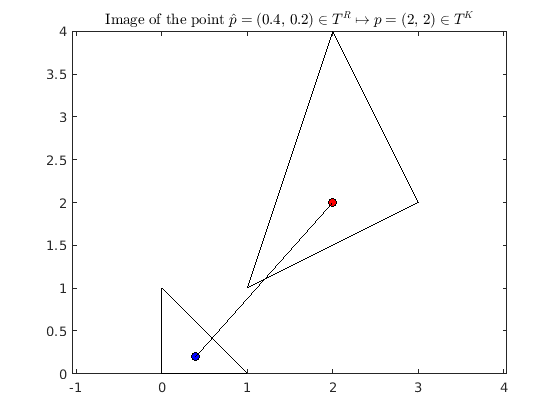

linePlot=[pR;pK]; %to plot a line joining pR and its image, pK
vplotK = [vertexsK; vertexsK(1,:)]; %Add the 1st. point at the last row,
vplotR = [vertexsR; vertexsR(1,:)]; %just to plot closed triangles.

%plot triangle R, and point pR:
plot(vplotR(:,1),vplotR(:,2),'-','color','black')
hold on
axis equal
plot(pR(1,1),pR(1,2),'o','Marker','o','MarkerFaceColor','blue',...
    'MarkerEdgeColor','black','lineWidth',1)

%plot triangle K, and polnt pK
plot(vplotK(:,1),vplotK(:,2),'-','color','black')
plot(pK(1,1),pK(1,2),'o','Marker','o','MarkerFaceColor','red',...
    'MarkerEdgeColor','black','lineWidth',1)
    
%Finaly, we plot a line joining pR and pK
plot(linePlot(:,1),linePlot(:,2),'-','color','black')
titleTxt = ['Image of the point $\hat{p} = ($',num2str(pR(1,1)),', ',...
    num2str(pR(1,2)),'$)\in T^{R}\mapsto p = ($',num2str(pK(1,1)),', ',... 
    num2str(pK(1,2)),'$)\in T^{K}$'];
title(titleTxt,'interpreter','LaTeX')
hold off